# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 09-Oct-2021 10:00:40

## Create the Array of Layers

layers = [
    imageInputLayer([224 224 3],"Name","imageinput")
    convolution2dLayer([3 3],64,"Name","conv_1","Padding",[1 1 1 1])
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],64,"Name","conv_2","Padding",[1 1 1 1])
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv_3","Padding",[1 1 1 1])
    reluLayer("Name","relu_3")
    convolution2dLayer([3 3],128,"Name","conv_4","Padding",[1 1 1 1])
    reluLayer("Name","relu_4")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv_5","Padding",[1 1 1 1])
    reluLayer("Name","relu_5")
    convolution2dLayer([3 3],256,"Name","conv_6","Padding",[1 1 1 1])
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],256,"Name","conv_7","Padding",[1 1 1 1])
    reluLayer("Name","relu_7")
    convolution2dLayer([3 3],256,"Name","conv_8","Padding",[1 1 1 1])
    reluLayer("Name","relu_8")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv_9","Padding",[1 1 1 1])
    reluLayer("Name","relu_9")
    convolution2dLayer([3 3],512,"Name","conv_10","Padding",[1 1 1 1])
    reluLayer("Name","relu_10")
    convolution2dLayer([3 3],512,"Name","conv_11","Padding",[1 1 1 1])
    reluLayer("Name","relu_11")
    convolution2dLayer([3 3],512,"Name","conv_12","Padding",[1 1 1 1])
    reluLayer("Name","relu_12")
    maxPooling2dLayer([2 2],"Name","maxpool_4","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv_13","Padding",[1 1 1 1])
    reluLayer("Name","relu_13")
    convolution2dLayer([3 3],512,"Name","conv_14","Padding",[1 1 1 1])
    reluLayer("Name","relu_14")
    convolution2dLayer([3 3],512,"Name","conv_15","Padding",[1 1 1 1])
    reluLayer("Name","relu_15")
    convolution2dLayer([3 3],512,"Name","conv_16","Padding",[1 1 1 1])
    reluLayer("Name","relu_16")
    maxPooling2dLayer([2 2],"Name","maxpool_5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc_1")
    reluLayer("Name","relu_17")
    dropoutLayer(0.5,"Name","dropout_1")
    fullyConnectedLayer(4096,"Name","fc_2")
    reluLayer("Name","relu_18")
    dropoutLayer(0.5,"Name","dropout_2")
    fullyConnectedLayer(4,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot the Layers

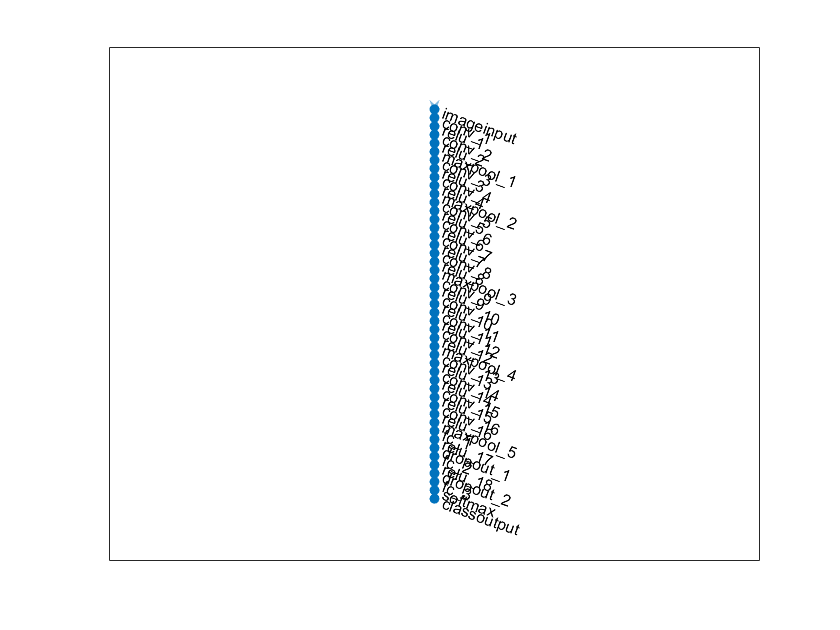

plot(layerGraph(layers));